# EECS 965 Homework 04                                 William Powers 2025

#### ***1. Determine the correct threshold ***$y\prime$* for a decision rule of the form:*  Choose  $H_1$  if  $T_d = x > y\prime$ 

Given the two hypotheses $H_0 = w_1$ and $H_1 = w_1 + w_2$ are equally probable a priori and that $w_1$ and $w_2$ are both exponentially distributed random variables, there a posteriori probabilities are desribed by


$$p(H_0|x) = \frac{p(x|H_0)p(H_0)}{\sum_{i=0, 1} p(x|H_i)p(H_i)} = 

\frac{ \left( \lambda_1 e^{-\lambda_1x} \right) (1/2) }{ \left( \lambda_1 e^{-\lambda_1x} \right)(1/2) + \left( \lambda_2 e^{-\lambda_2x} \right)(1/2) }=

\frac{ \left( \lambda_1 e^{-\lambda_1x} \right) }{ \left( \lambda_1 e^{-\lambda_1x} \right) + \left( \lambda_2 e^{-\lambda_2x} \right) }$$



$$p(H_1|x) = \frac{p(x|H_1)p(H_1)}{\sum_{i=0, 1} p(x|H_i)p(H_i)} = 

\frac{ \left( \lambda_1 e^{-\lambda_1x} + \lambda_2 e^{-\lambda_2x} \right) (1/2) }{ \left( \lambda_1 e^{-\lambda_1x} \right)(1/2) + \left( \lambda_1 e^{-\lambda_1x} + \lambda_2 e^{-\lambda_2x} \right) (1/2) } = 

\frac{ \left( \lambda_1 e^{-\lambda_1x} + \lambda_2 e^{-\lambda_2x} \right)  }{ \left(  2\lambda_1 e^{-\lambda_1x} + \lambda_2 e^{-\lambda_2x} \right)  }$$


From this a posteriori expression, the decision rule for $H_1$ is thus written as

Choose  $H_1$  if  $p(H_1|x) > p(H_0|x)$

Dividing the entire rule by $p(H_0|x)$, noting that each a posteriori probability is equal to its liklihood probability of that hypothesis, frames the liklihood ratio test

Choose  $H_1$ if  $\frac{p(H_1|x)}{p(H_0|x)} =L(x)> 1.0$

To determine this liklihood ratio in terms of the detection statistic $T_d(x)$, further simplifications of $L(x)$ are required. Taking the natural log of both sides of the inequality gives


$$\ln(p(H_1|x)) - \ln(p(H_0|x)) > \ln(1.0)$$


where


$$\ln(p(H_1|x) = \ln \left( \lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} \right) - \ln \left( 2\lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} \right)$$



$$\ln(p(H_0|x))=  \ln \left( \frac{\lambda_1}{ \lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} } \right)$$


thus the expression becomes


$$\ln \left( \lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} \right) - \ln \left( 2\lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} \right) 

-

\ln \left( \frac{\lambda_1}{ \lambda_1 + \lambda_2 e^{-(\lambda_2 - \lambda_1)x} } \right)

> 0$$


Solving for and expression only containing $x$ and no other hypothesis dependent variables in the above inequality forms the detection statistic $T_d(x)$ in which all operations perserve the decision boundary.


$$T_d(x) = x < -\frac{1}{\lambda_2 - \lambda_1} \ln \left( \frac{\lambda_1}{2\lambda_2} (\sqrt{5}-1) \right)$$


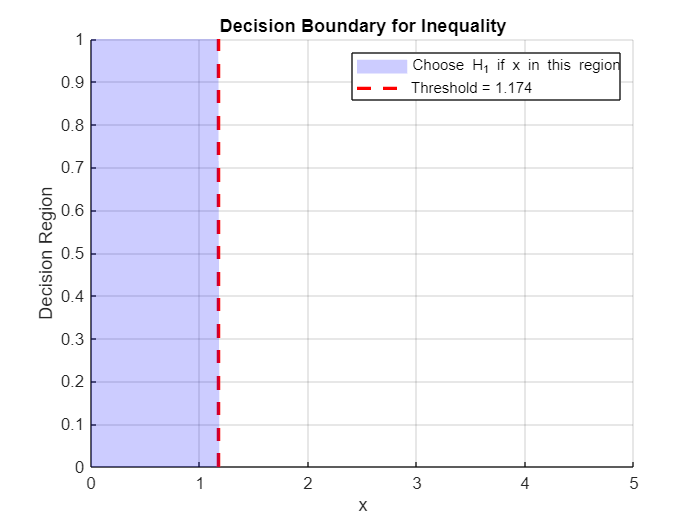

% exponential lambda values
lambda1 = 1;
lambda2 = 2;

% compute detection statistic threshold
threshold = -(1/(lambda2 - lambda1)) * log((lambda1/(2*lambda2)) * (sqrt(5) - 1));

% X-axis range
x = linspace(0, 5, 500);

% evaluate decision boudary inequality
x = linspace(0, 5, 500);
decisionRegion = x < threshold;

% plot results
figure; hold on; grid on;
plot([threshold threshold], [0 1], 'r--', 'LineWidth', 2);
area(x, decisionRegion, 'FaceAlpha', 0.2, 'FaceColor', 'b', 'EdgeColor', 'none');
xlabel('x'); ylabel('Decision Region');
title('Decision Boundary for Inequality');
legend(sprintf('Threshold = %.3f', threshold), 'Choose H_1 if x in this region');